%% TEST SCRIPT for DroneInverseDynamicsStep

clear; clc;

% Parameters
m  = 1.5;        % mass [kg]
dt = 0.01;       % timestep [s]

% Initial state: [x y z vx vy vz]
s0 = [0 0 0 0 0 0];

% Input force
u_hover = [0 0 0];        % no force
u_push  = [100 100 100];        % force in x

### TEST 1: Dimension check

% DroneForwardDynamicsStep([0 0 0 0 0], u_push, m, dt)
% DroneForwardDynamicsStep(s0, [0 0], m, dt)
% DroneForwardDynamicsStep(s0, u_push, 0, dt)
% DroneForwardDynamicsStep(s0, u_push, dt, 0)

### TEST 2: Zero Input Behaviour

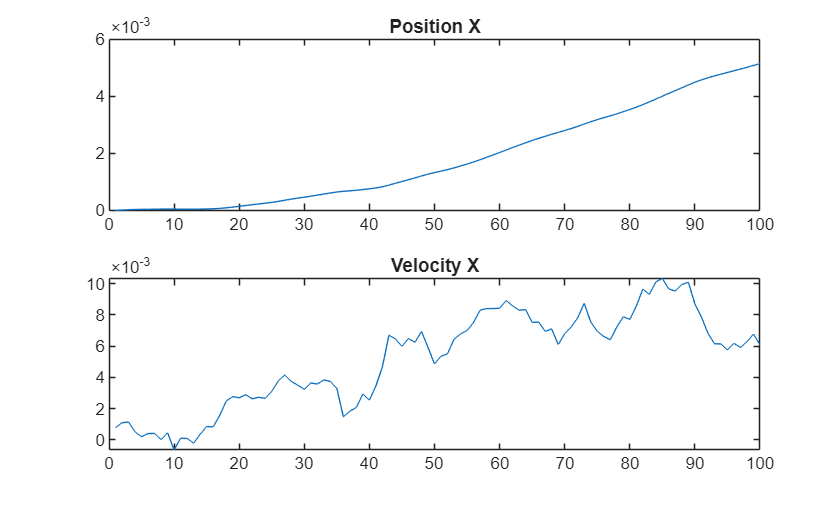

N = 100;
s_res = zeros(N,6);
s = s0;

for k = 1:N
    s = DroneForwardDynamicsStep(s, u_hover, m, dt);
    s_res(k,:) = s;
end

% Acceleration should be roughly zero, velocity and position should be roughly constant

figure;
subplot(2,1,1);
plot(s_res(:,2)); title('Position X');
subplot(2,1,2);
plot(s_res(:,5)); title('Velocity X');

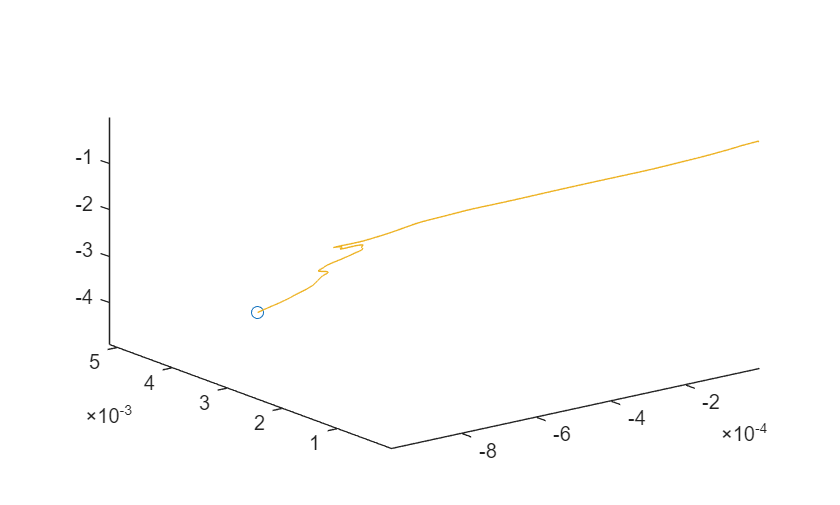

figure
grid on
comet3(s_res(:,1), s_res(:,2), s_res(:,3))

### TEST 3: Constant Force Behaviour

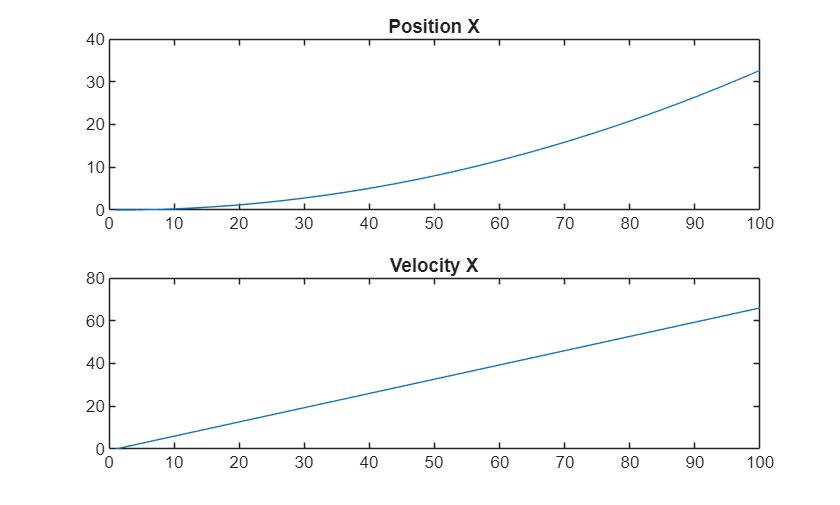

N = 100;
s_res = zeros(N,6);
s_res(1,:) = s0;

for k = 1:N-1
    s_res(k+1,:) = DroneForwardDynamicsStep(s_res(k,:), u_push, m, dt);
end

% Acceleration should be roughly zero, velocity and position should be roughly constant

figure;
subplot(2,1,1);
plot(s_res(:,1)); title('Position X');
subplot(2,1,2);
plot(s_res(:,4)); title('Velocity X');

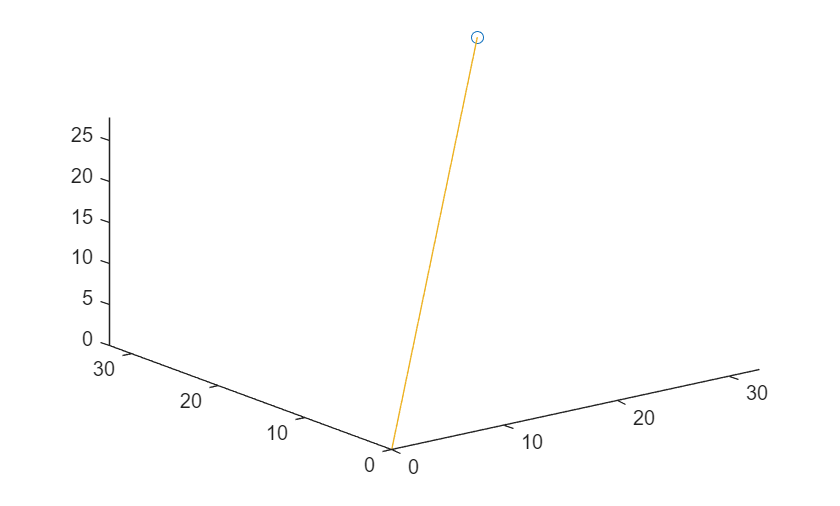

figure
grid on
comet3(s_res(:,1), s_res(:,2), s_res(:,3))

### TEST 4: Simple PID Controller

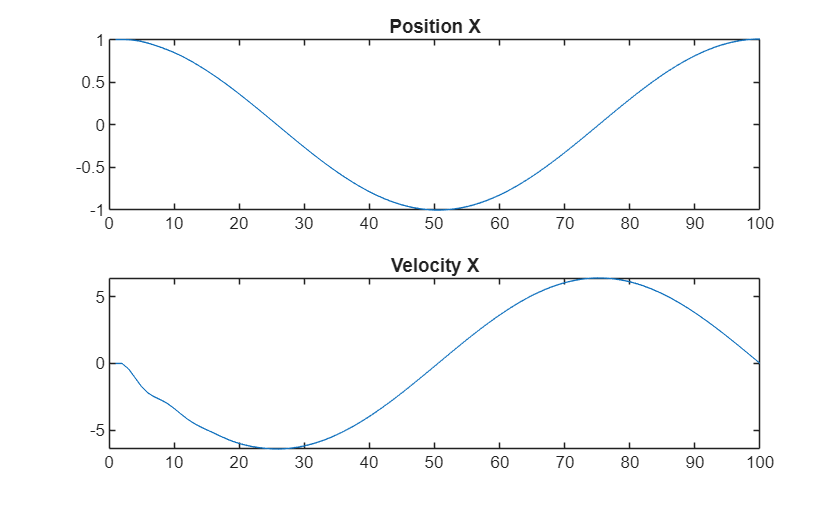

% now we use a reference trajectory of a spiral along z, from t=0, to t=10
kp = 10000;
kd = 100;
dt = 0.01;
N = 100;
t0 = 0;
tf = t0 + N*dt;
t = linspace(t0, tf, N);
s_ref = [cos(2*pi*t)', sin(2*pi*t)', t', -2*pi*sin(2*pi*t)', 2*pi*cos(2*pi*t)', ones(N, 1)]; % Reference trajectory in 3D

% then we build a simple P controller to control the force correctly:
s0 = s_ref(1, :);
s_res = zeros(N,6);
s_res(1,:) = s0;
for k = 1:N-1
    u = kp*(s_ref(k, 1:3) - s_res(k, 1:3)) + kd*(s_ref(k, 4:6) - s_res(k, 4:6));
    s_res(k+1,:) = DroneForwardDynamicsStep(s_res(k,:), u , m, dt);
end
    
figure;
subplot(2,1,1);
plot(s_res(:,1)); title('Position X');
subplot(2,1,2);
plot(s_res(:,4)); title('Velocity X');

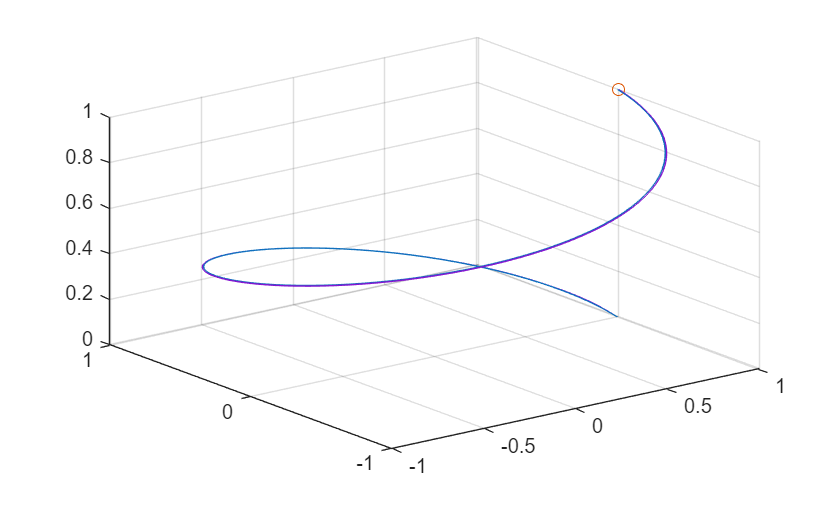

figure
  x = s_ref(:,1);
  y = s_ref(:,2);
  z = s_ref(:,3);
  plot3(x,y,z)
hold on
grid on
comet3(s_res(:,1), s_res(:,2), s_res(:,3))

### Test 6: Spiral

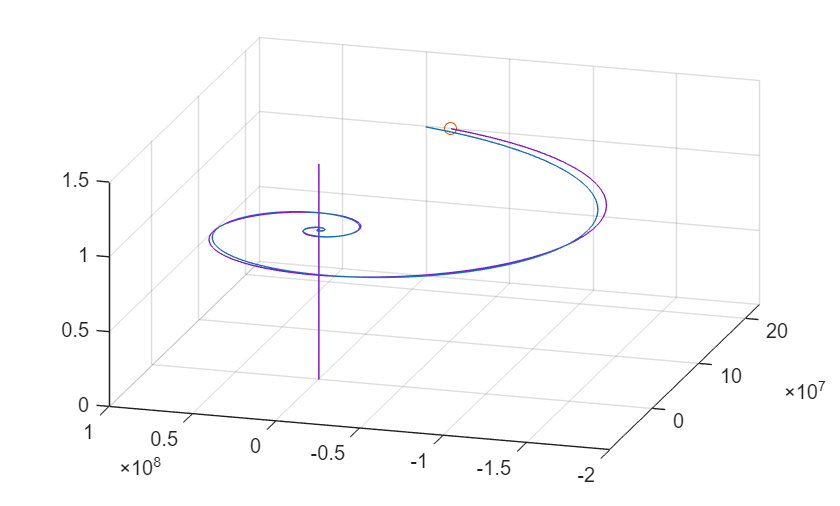

phi = (1 + sqrt(5)) / 2; 
kp = 10000;
kd = 100;
dt = 0.01;
N = 1000;
t0 = 0;
tf = t0 + N*dt;
t = linspace(t0, tf, N);
x_ref = (phi.^(4*t).*cos(2*pi*t))';
y_ref = (phi.^(4*t).*sin(2*pi*t))';
xd_ref = gradient(x_ref, dt);
yd_ref = gradient(y_ref, dt);

% then we build a simple P controller to control the force correctly:
%first measure
s0 = [0, 0, 0, 0, 0, 0];
s_res = zeros(N,6);
s_res(1,:) = s0;
for k = 1:N-1
    % measure
    % ...
    % trajectory calculation
    s_ref = [x_ref(k), y_ref(k), 1, xd_ref(k), y_ref(k), 0];
    % control
    u = kp*(s_ref(1:3) - s_res(k, 1:3)) + kd*(s_ref(4:6) - s_res(k, 4:6));
    % drone dynamic
    s_res(k+1,:) = DroneForwardDynamicsStep(s_res(k,:), u , m, dt);
end
figure
  plot3(x_ref,y_ref,ones(1, N))
hold on
grid on
comet3(s_res(:,1), s_res(:,2), s_res(:,3))

### Test 8: functions

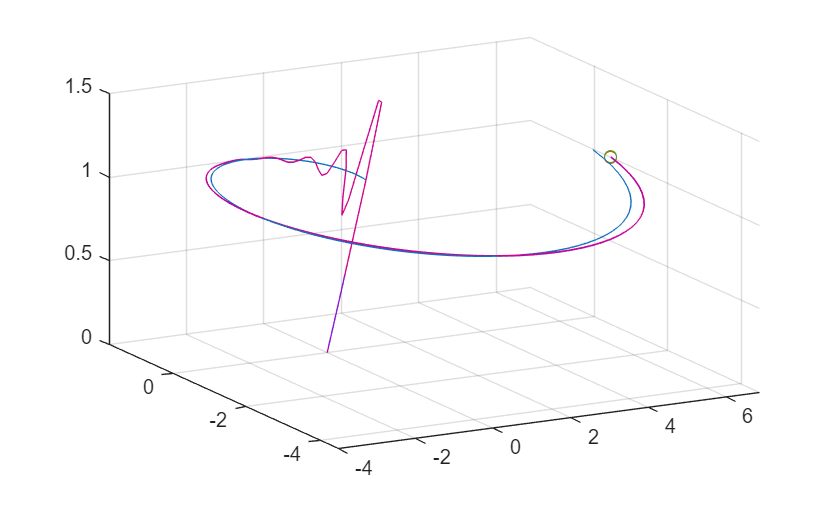

phi = (1 + sqrt(5)) / 2; 
kp = 10000;
kd = 100;
dt = 0.01;
N = 100;
t0 = 0;
tf = t0 + N*dt;
t = linspace(t0, tf, N);
x_ref = (phi.^(4*t).*cos(2*pi*t))';
y_ref = (phi.^(4*t).*sin(2*pi*t))';
xd_ref = gradient(x_ref, dt);
yd_ref = gradient(y_ref, dt);

% then we build a simple P controller to control the force correctly:
%first measure
s0 = [0, 0, 0, 0, 0, 0];
s_res = zeros(N,6);
s_res(1,:) = s0;
s_res2 = zeros(N,6);
s_res2(1,:) = s0;
for k = 1:N-1
    % measure
    % ...
    % trajectory calculation
    s_ref = [x_ref(k), y_ref(k), 1, xd_ref(k), y_ref(k), 0];
    % control
    u = kp*(s_ref(1:3) - s_res(k, 1:3)) + kd*(s_ref(4:6) - s_res(k, 4:6));
    u2 = DronePIDControllerStep(s_res(k, :), s_ref, kp, kd);
    % drone dynamic
    s_res(k+1,:) = DroneForwardDynamicsStep(s_res(k,:), u , m, dt);
    s_res2(k+1,:) = DroneForwardDynamicsStep(s_res2(k,:), u2 , m, dt);
end
figure
plot3(x_ref,y_ref,ones(1, N))
hold on
grid on
comet3(s_res(:,1), s_res(:,2), s_res(:,3))
comet3(s_res2(:,1), s_res2(:,2), s_res2(:,3))


DronePIDControllerStep(s, s_ref, kp, kd)

Unrecognized function or variable 's'.